# **PESTools - Example 002 - Brillouin Zone Navigation for SX-ARPES**

## (1) EXAMPLE: BZ navigation of Si(001) Gamma-Points

#### (A) Extracting the real- and reciprocal-space crystal structure

-> Extracting 3D BZ...


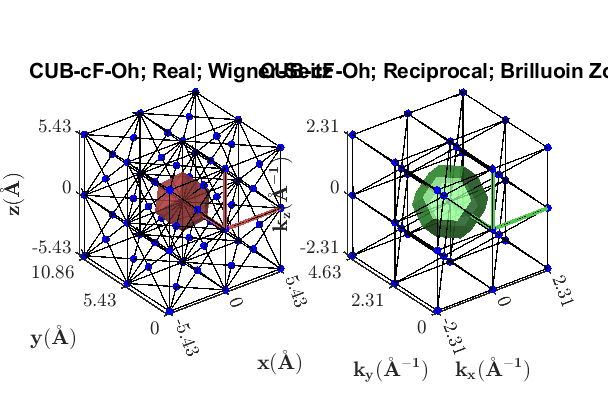

close all; clear all;
pp = plot_props();
[realStr, reciStr] = extract_lattice([], 1);

-> Extracting plane slice of BZ...


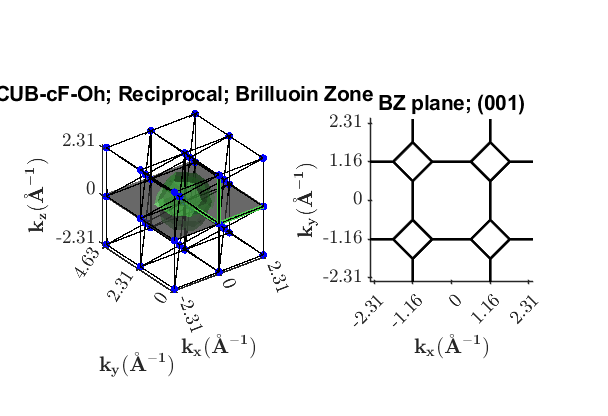

bzOverlay = extract_bz_overlay(reciStr, "(001)", 1);

#### (B) Plotting the kz positions for a given set of photon energies

help extract_hv_overlay;

  hvOverlay = extract_hv_overlay(hv, navi_args, bzOverlay, plot_results)
    This is a function that extracts the crystallographic vectors
    of a general crystal structure in both real- and reciprocal-
    space based on the inputs. All 14 Bravais lattices can be 
    defined, including primitive-, base-, face- and body-centered
    lattices. The outputs are two MATLAB structures that contain
    all of the real- and reciprocal-space data.
 
    IN:
    - hv:        	single or 1x2 vector of [minHv, maxHv] for the user defined photon energy.
    - navi_args:	MATLAB data structure containing all of the navigation arguments below;
        .(ePhi):                	Work function of analyser
        .(alpha):                   Angle between analyser and sample normal (July 2022: 20deg, from August 2022: 9deg).
        .(thtM):                	Primary manipulator rotation
        .(eBref):                	Binding energy reference
        .(thtAref):             	Analyser an

% (1) DEFINE THE ARPES GEOMETRY
navi_args = struct();
navi_args.ePhi      = 4.5; 
navi_args.alpha     = 9.0;  % present geometry 9deg; Old geometry 20deg;
navi_args.thtM      = 0; 
navi_args.eBref     = 0; 
navi_args.thtAref	= 0; 
navi_args.kxref     = 0; 
navi_args.tltM      = 0; 
navi_args.V000      = 12.57; 
% (2) DEFINE THE PHOTON ENERGIES TO PLOT
if ishandle(360579); close(360579); end
extract_hv_overlay([10,200], navi_args, bzOverlay, 1);

-> Extracting k-space ARPES scan line...


extract_hv_overlay([310,1600], navi_args, bzOverlay, 1);

-> Extracting k-space ARPES scan line...


extract_hv_overlay([2000,6000], navi_args, bzOverlay, 1);

-> Extracting k-space ARPES scan line...


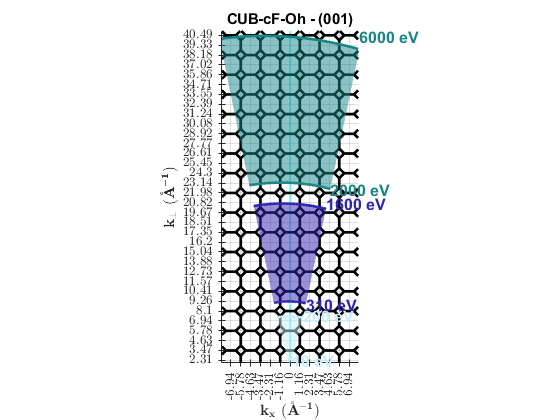

% (3) FORMATTING THE FIGURE
axis([-8, 8, 2.0, 41]);

#### (C) Plotting the photon energies at the Gamma Points

-> Extracting k-space ARPES scan line...


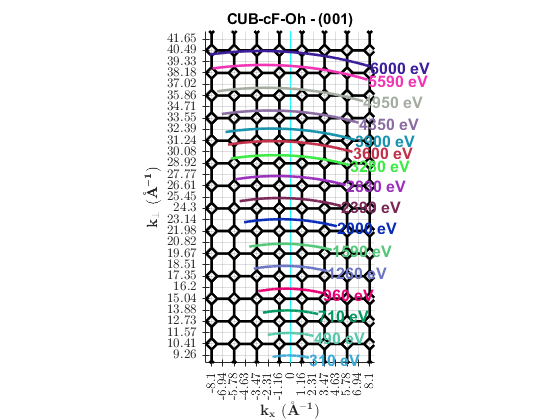

if ishandle(360579); close(360579); end
hv_gamma = [...
    310, 490, 710, 960, 1260, 1590,...
    2000, 2390, 2830, 3280, 3600, 3900,...
    4350, 4950, 5590, 6000];
extract_hv_overlay(hv_gamma, navi_args, bzOverlay, 1);